There are currently 3 defined kernel types:

EQ - exponential Quadratic (SE squared exponential)

RQ - Rational Quadratic (alpha=1)

Matern52

These kernels can be added subtracted multiplied and divided

The GP class takes a mean function and a kernel.

it then can be conditioned on data x and y and can then be trained using mean aposteriori HP selection.


x1 = rand(10,2);
y1 = 2*(double(rand(10,1)<0.5)-0.5);


d = kernels.Matern52(1,[2 2]);

Z = SVM(d);

Z1 = Z.condition(x1,y1);

Z2 = Z1.train();

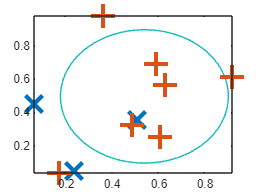

utils.isoplot(Z2,2,1)
hold on

ij = find(y1==1);
plot(x1(ij,1),x1(ij,2),'x','MarkerSize',18,'LineWidth',3)

hold on

ij = find(y1==-1);
plot(x1(ij,1),x1(ij,2),'+','MarkerSize',18,'LineWidth',3)